inputs

func = @(x) x.^2 - 4.*x + 4 - log(x)

func = function_handle with value:
    @(x)x.^2-4.*x+4-log(x)



a = 1

a = 1

b = 2

b = 2

max_iter = 100

max_iter = 100


% tolerance
tol = 1e-5

tol = 1.0000e-05

check if the interval is crossing the x-axis

if func(a) * func(b) > 0
    error("the interval does not bracket a root")
end

% step 1
iter = 1

iter = 1

f_a = func(a)

f_a = 1

f_b = func(b) % not necessary

f_b = -0.6931


results = table()


results =

  0×0 empty table

	Get insights using Copilot



converged = false

converged = logical
   0


% step 2
while iter <= max_iter
    % step 3
    p = a + (b - a)/2
    f_p = func(p)

    results(end+1,:) = table(...
        iter, a, b, p, f_a, f_b ,f_p ...
    )

    % step 4 - convergence test
    if abs(f_p) < tol || (b - a)/2 < tol
        converged = true
        break % use return if it is a function
    end

    % redefining variables
    % step 5
    iter = iter + 1

    % step 6 - choose new interval
    if f_a .* f_p > 0
        a = p
        f_a = f_p
    else
        b = p
        f_b = f_p % not necessary
    end

end

p = 1.5000

f_p = -0.1555

results = 1×7 table
    iter    a    b     p     f_a      f_b         f_p   
    ____    _    _    ___    ___    ________    ________

     1      1    2    1.5     1     -0.69315    -0.15547

	Get insights using Copilot


iter = 2

b = 1.5000

f_b = -0.1555

p = 1.2500

f_p = 0.3394

results = 2×7 table
    iter    a     b      p      f_a      f_b         f_p   
    ____    _    ___    ____    ___    ________    ________

     1      1      2     1.5     1     -0.69315    -0.15547
     2      1    1.5    1.25     1     -0.15547     0.33936

	Get insights using Copilot


iter = 3

a = 1.2500

f_a = 0.3394

p = 1.3750

f_p = 0.0722

results = 3×7 table
    iter     a       b       p        f_a        f_b         f_p   
    ____    ____    ___    _____    _______    ________    ________

     1         1      2      1.5          1    -0.69315    -0.15547
     2         1    1.5     1.25          1    -0.15547     0.33936
     3      1.25    1.5    1.375    0.33936    -0.15547    0.072171

	Get insights using Copilot


iter = 4

a = 1.3750

f_a = 0.0722

p = 1.4375

f_p = -0.0465

results = 4×7 table
    iter      a       b       p         f_a         f_b          f_p   
    ____    _____    ___    ______    ________    ________    _________

     1          1      2       1.5           1    -0.69315     -0.15547
     2          1    1.5      1.25           1    -0.15547      0.33936
     3       1.25    1.5     1.375     0.33936    -0.15547     0.072171
     4      1.375    1.5    1.4375    0.072171    -0.15547    -0.046499

	Get insights using Copilot


iter = 5

b = 1.4375

f_b = -0.0465

p = 1.4062

f_p = 0.0116

results = 5×7 table
    iter      a        b         p         f_a          f_b          f_p   
    ____    _____    ______    ______    ________    _________    _________

     1          1         2       1.5           1     -0.69315     -0.15547
     2          1       1.5      1.25           1     -0.15547      0.33936
     3       1.25       1.5     1.375     0.33936     -0.15547     0.072171
     4      1.375       1.5    1.4375    0.072171     -0.15547    -0.046499
     5      1.375    1.4375    1.4062    0.072171    -0.046499     0.011612

	Get insights using Copilot


iter = 6

a = 1.4062

f_a = 0.0116

p = 1.4219

f_p = -0.0177

results = 6×7 table
    iter      a         b         p         f_a          f_b          f_p   
    ____    ______    ______    ______    ________    _________    _________

     1           1         2       1.5           1     -0.69315     -0.15547
     2           1       1.5      1.25           1     -0.15547      0.33936
     3        1.25       1.5     1.375     0.33936     -0.15547     0.072171
     4       1.375       1.5    1.4375    0.072171     -0.15547    -0.046499
     5       1.375    1.4375    1.4062    0.072171    -0.046499     0.011612
     6      1.4062    1.4375    1.4219    0.011612    -0.046499    -0.017748

	Get insights using Copilot


iter = 7

b = 1.4219

f_b = -0.0177

p = 1.4141

f_p = -0.0031

results = 7×7 table
    iter      a         b         p         f_a          f_b          f_p   
    ____    ______    ______    ______    ________    _________    _________

     1           1         2       1.5           1     -0.69315     -0.15547
     2           1       1.5      1.25           1     -0.15547      0.33936
     3        1.25       1.5     1.375     0.33936     -0.15547     0.072171
     4       1.375       1.5    1.4375    0.072171     -0.15547    -0.046499
     5       1.375    1.4375    1.4062    0.072171    -0.046499     0.011612
     6      1.4062    1.4375    1.4219    0.011612    -0.046499    -0.017748
     7      1.4062    1.4219    1.4141    0.011612    -0.017748    -0.003144

	

iter = 8

b = 1.4141

f_b = -0.0031

p = 1.4102

f_p = 0.0042

results = 8×7 table
    iter      a         b         p         f_a          f_b          f_p   
    ____    ______    ______    ______    ________    _________    _________

     1           1         2       1.5           1     -0.69315     -0.15547
     2           1       1.5      1.25           1     -0.15547      0.33936
     3        1.25       1.5     1.375     0.33936     -0.15547     0.072171
     4       1.375       1.5    1.4375    0.072171     -0.15547    -0.046499
     5       1.375    1.4375    1.4062    0.072171    -0.046499     0.011612
     6      1.4062    1.4375    1.4219    0.011612    -0.046499    -0.017748
     7      1.4062    1.4219    1.4141    0.011612    -0.017748    -0.003144
     8      1.4062    1.4141    1.4102    0.0116

iter = 9

a = 1.4102

f_a = 0.0042

p = 1.4121

f_p = 5.3079e-04

results = 9×7 table
    iter      a         b         p          f_a          f_b          f_p    
    ____    ______    ______    ______    _________    _________    __________

     1           1         2       1.5            1     -0.69315      -0.15547
     2           1       1.5      1.25            1     -0.15547       0.33936
     3        1.25       1.5     1.375      0.33936     -0.15547      0.072171
     4       1.375       1.5    1.4375     0.072171     -0.15547     -0.046499
     5       1.375    1.4375    1.4062     0.072171    -0.046499      0.011612
     6      1.4062    1.4375    1.4219     0.011612    -0.046499     -0.017748
     7      1.4062    1.4219    1.4141     0.011612    -0.017748     -0.003144
     8      1.4062    1.4141  

iter = 10

a = 1.4121

f_a = 5.3079e-04

p = 1.4131

f_p = -0.0013

results = 10×7 table
    iter      a         b         p          f_a           f_b          f_p    
    ____    ______    ______    ______    __________    _________    __________

      1          1         2       1.5             1     -0.69315      -0.15547
      2          1       1.5      1.25             1     -0.15547       0.33936
      3       1.25       1.5     1.375       0.33936     -0.15547      0.072171
      4      1.375       1.5    1.4375      0.072171     -0.15547     -0.046499
      5      1.375    1.4375    1.4062      0.072171    -0.046499      0.011612
      6     1.4062    1.4375    1.4219      0.011612    -0.046499     -0.017748
      7     1.4062    1.4219    1.4141      0.011612    -0.017748     -0.003144
      8     1.4062  

iter = 11

b = 1.4131

f_b = -0.0013

p = 1.4126

f_p = -3.8881e-04

results = 11×7 table
    iter      a         b         p          f_a           f_b            f_p    
    ____    ______    ______    ______    __________    __________    ___________

      1          1         2       1.5             1      -0.69315       -0.15547
      2          1       1.5      1.25             1      -0.15547        0.33936
      3       1.25       1.5     1.375       0.33936      -0.15547       0.072171
      4      1.375       1.5    1.4375      0.072171      -0.15547      -0.046499
      5      1.375    1.4375    1.4062      0.072171     -0.046499       0.011612
      6     1.4062    1.4375    1.4219      0.011612     -0.046499      -0.017748
      7     1.4062    1.4219    1.4141      0.011612     -0.017748      -0.003144
  

iter = 12

b = 1.4126

f_b = -3.8881e-04

p = 1.4124

f_p = 7.0918e-05

results = 12×7 table
    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             1       -0.69315       -0.15547
      2          1       1.5      1.25             1       -0.15547        0.33936
      3       1.25       1.5     1.375       0.33936       -0.15547       0.072171
      4      1.375       1.5    1.4375      0.072171       -0.15547      -0.046499
      5      1.375    1.4375    1.4062      0.072171      -0.046499       0.011612
      6     1.4062    1.4375    1.4219      0.011612      -0.046499      -0.017748
      7     1.4062    1.4219    1.4141      0.011612      -0.017748      -0.

iter = 13

a = 1.4124

f_a = 7.0918e-05

p = 1.4125

f_p = -1.5896e-04

results = 13×7 table
    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             1       -0.69315       -0.15547
      2          1       1.5      1.25             1       -0.15547        0.33936
      3       1.25       1.5     1.375       0.33936       -0.15547       0.072171
      4      1.375       1.5    1.4375      0.072171       -0.15547      -0.046499
      5      1.375    1.4375    1.4062      0.072171      -0.046499       0.011612
      6     1.4062    1.4375    1.4219      0.011612      -0.046499      -0.017748
      7     1.4062    1.4219    1.4141      0.011612      -0.017748      -0.

iter = 14

b = 1.4125

f_b = -1.5896e-04

p = 1.4124

f_p = -4.4027e-05

results = 14×7 table
    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             1       -0.69315       -0.15547
      2          1       1.5      1.25             1       -0.15547        0.33936
      3       1.25       1.5     1.375       0.33936       -0.15547       0.072171
      4      1.375       1.5    1.4375      0.072171       -0.15547      -0.046499
      5      1.375    1.4375    1.4062      0.072171      -0.046499       0.011612
      6     1.4062    1.4375    1.4219      0.011612      -0.046499      -0.017748
      7     1.4062    1.4219    1.4141      0.011612      -0.017748      -0.

iter = 15

b = 1.4124

f_b = -4.4027e-05

p = 1.4124

f_p = 1.3444e-05

results = 15×7 table
    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             1       -0.69315       -0.15547
      2          1       1.5      1.25             1       -0.15547        0.33936
      3       1.25       1.5     1.375       0.33936       -0.15547       0.072171
      4      1.375       1.5    1.4375      0.072171       -0.15547      -0.046499
      5      1.375    1.4375    1.4062      0.072171      -0.046499       0.011612
      6     1.4062    1.4375    1.4219      0.011612      -0.046499      -0.017748
      7     1.4062    1.4219    1.4141      0.011612      -0.017748      -0.

iter = 16

a = 1.4124

f_a = 1.3444e-05

p = 1.4124

f_p = -1.5292e-05

results = 16×7 table
    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             1       -0.69315       -0.15547
      2          1       1.5      1.25             1       -0.15547        0.33936
      3       1.25       1.5     1.375       0.33936       -0.15547       0.072171
      4      1.375       1.5    1.4375      0.072171       -0.15547      -0.046499
      5      1.375    1.4375    1.4062      0.072171      -0.046499       0.011612
      6     1.4062    1.4375    1.4219      0.011612      -0.046499      -0.017748
      7     1.4062    1.4219    1.4141      0.011612      -0.017748      -0.

iter = 17

b = 1.4124

f_b = -1.5292e-05

p = 1.4124

f_p = -9.2387e-07

results = 17×7 table
    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             1       -0.69315       -0.15547
      2          1       1.5      1.25             1       -0.15547        0.33936
      3       1.25       1.5     1.375       0.33936       -0.15547       0.072171
      4      1.375       1.5    1.4375      0.072171       -0.15547      -0.046499
      5      1.375    1.4375    1.4062      0.072171      -0.046499       0.011612
      6     1.4062    1.4375    1.4219      0.011612      -0.046499      -0.017748
      7     1.4062    1.4219    1.4141      0.011612      -0.017748      -0.

converged = logical
   1



if ~converged
    error('the method failed after %d iteration', max_iter)
end

disp(results)

    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             1       -0.69315       -0.15547
      2          1       1.5      1.25             1       -0.15547        0.33936
      3       1.25       1.5     1.375       0.33936       -0.15547       0.072171
      4      1.375       1.5    1.4375      0.072171       -0.15547      -0.046499
      5      1.375    1.4375    1.4062      0.072171      -0.046499       0.011612
      6     1.4062    1.4375    1.4219      0.011612      -0.046499      -0.017748
      7     1.4062    1.4219    1.4141      0.011612      -0.017748      -0.003144
      8     1.

plot

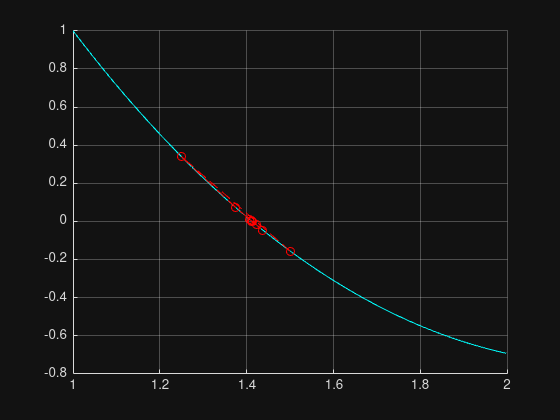

figure
hold on
fplot(func, [1, 2], 'c')
plot(results.p, results.f_p, 'r--o')
grid on
hold off